cd('/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001')
ExperimentName='20220425_109_AChmut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=11; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 1; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220510.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])
starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220510.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end



if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)


starting_reference_file = struct with fields:
       name: '20220425_109_AChmut_SW_001FLIM001.mat'
     folder: '/Volumes/PcSSDA/20220425_109_AChmut_SW_001'
       date: '25-Apr-2022 16:46:11'
      bytes: 2994
      isdir: 0
    datenum: 7.3864e+05


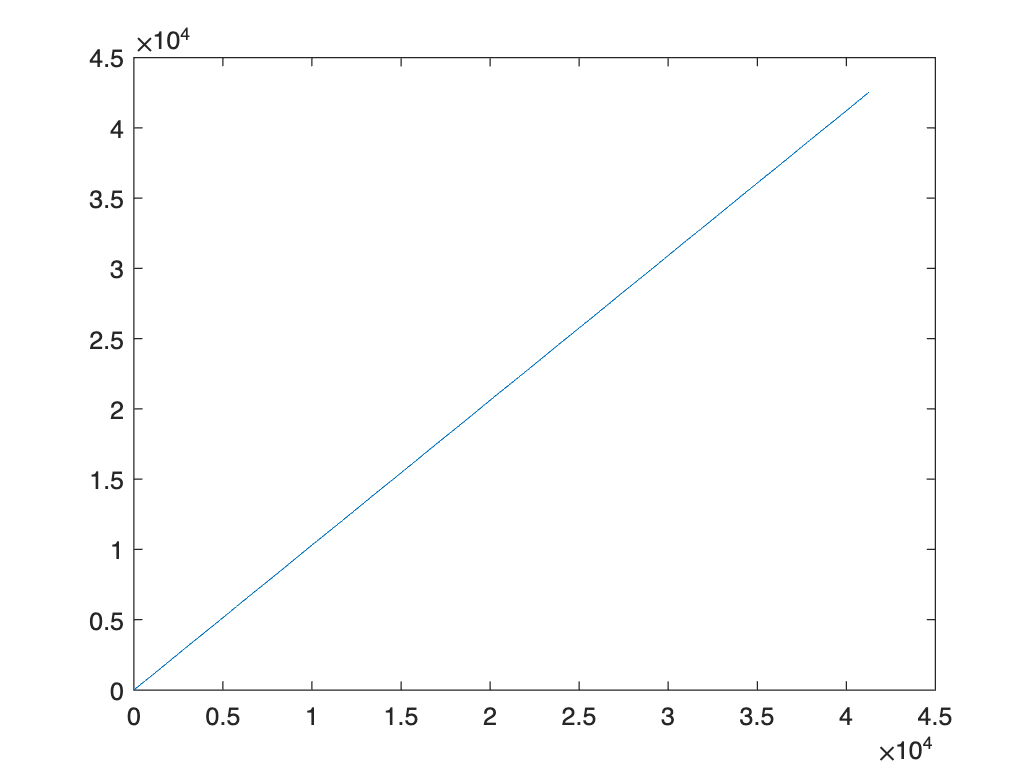


% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['extracted_data/StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end

states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename_plus=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220510.mat'];
    load(filename_plus);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);



mkdir([analysis_name,'csv_20220510'])


csv_name=[analysis_name,'csv_20220510/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)


save('FLP_analysis')

Saving wave object  ...
Saving wave object  ...
Saving wave object  ...


rawdat_dir=pwd;
fileprefix=ExperimentName;% '20220323_1629_SW_003';
filepostfix='20220510';
frequency=1;
constant=FirstAcq-1;
FigureVisible = 'off';
mouse='109mut';

EEGfile = 'extracted_data/downsampEEG_Acq21.npy'

scoring_python = 'extracted_data/StatesAcq21_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD0_21.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD2_21.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD3_21.mat'

Loading wave object file ...


FLiPfile = '20220425_109_AChmut_SW_001_analysis_11h_20220510.mat'

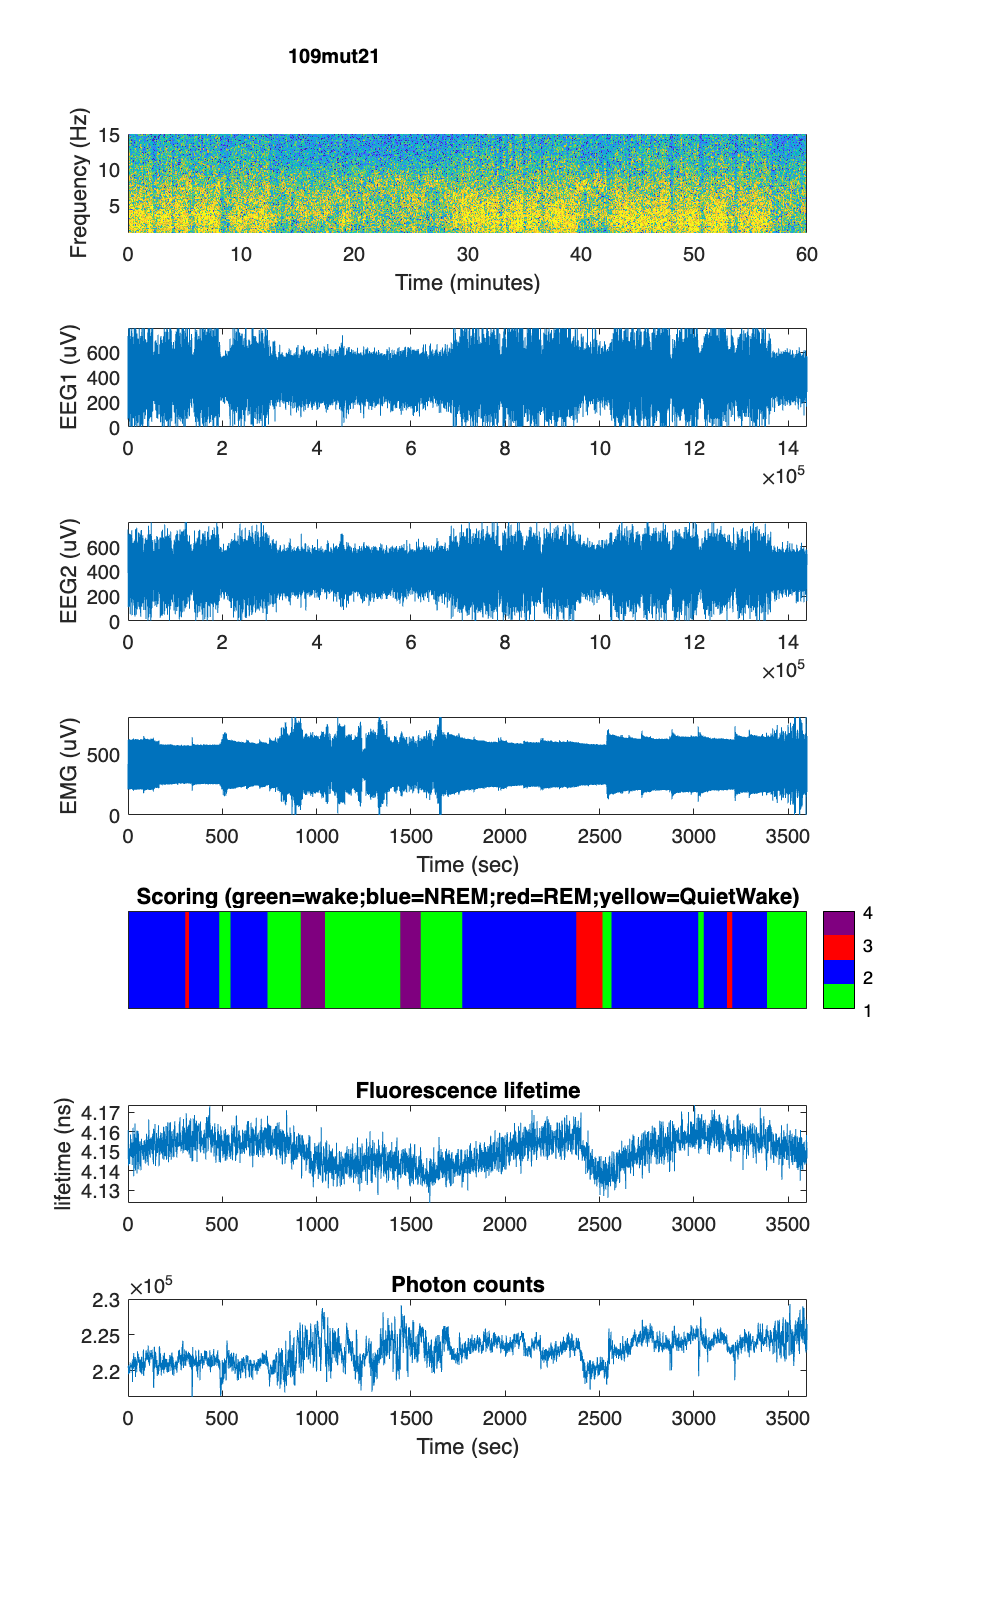

EEGfile = 'extracted_data/downsampEEG_Acq22.npy'

scoring_python = 'extracted_data/StatesAcq22_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD0_22.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD2_22.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD3_22.mat'

Loading wave object file ...


FLiPfile = '20220425_109_AChmut_SW_001_analysis_12h_20220510.mat'

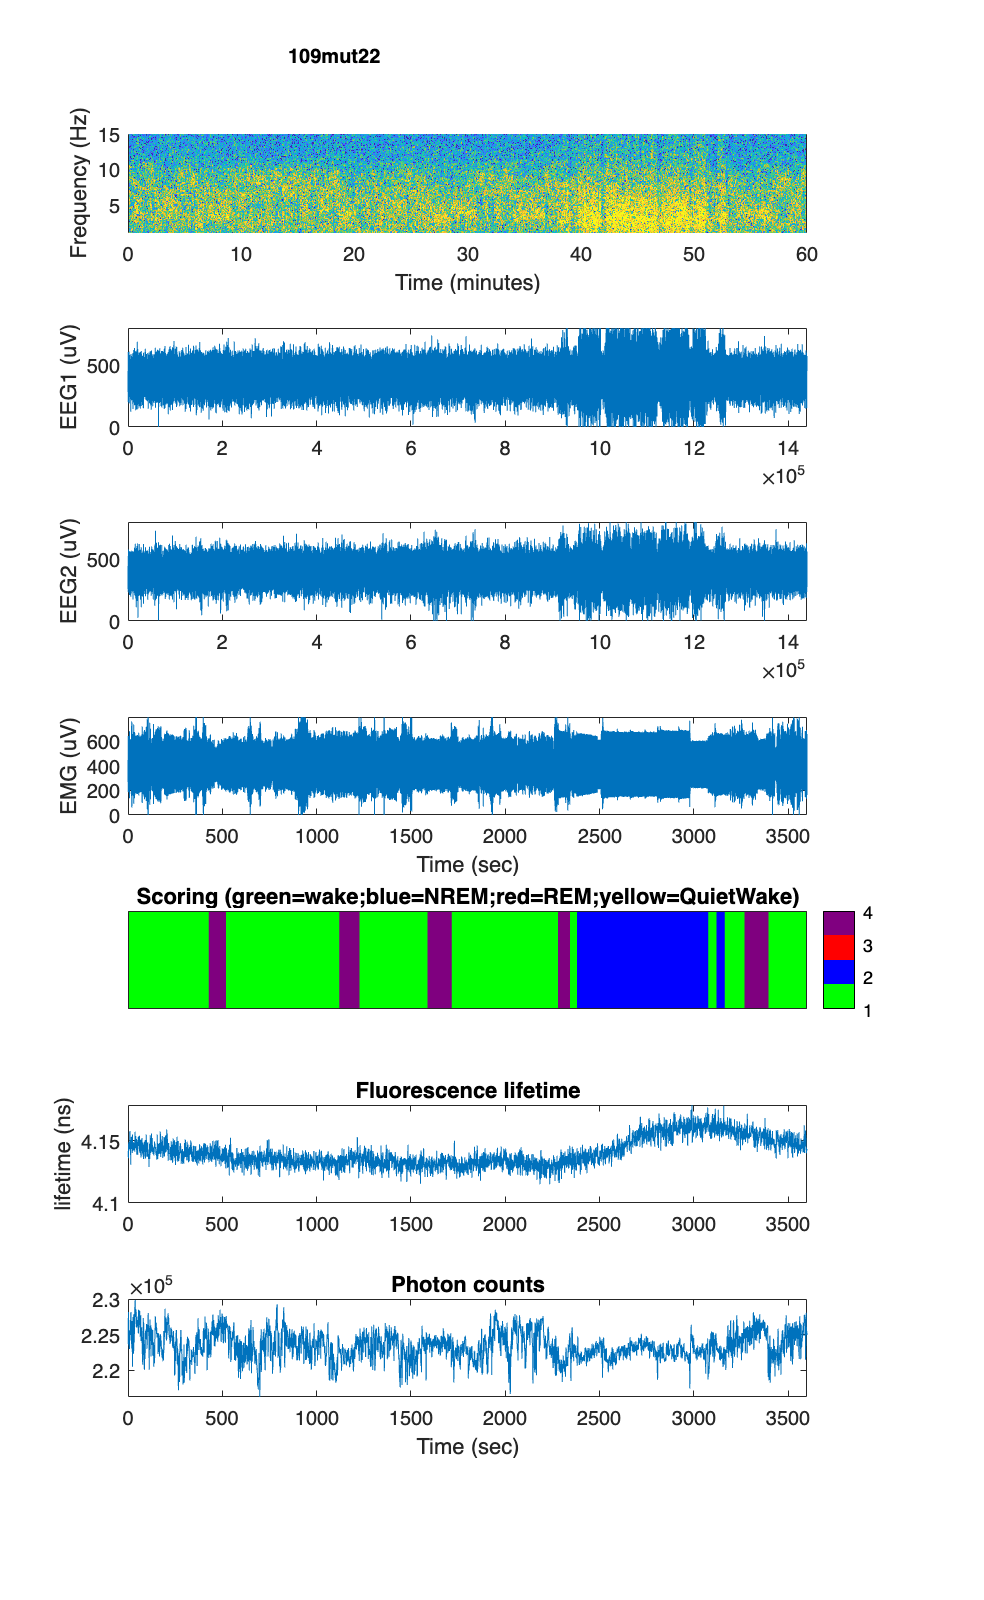

EEGfile = 'extracted_data/downsampEEG_Acq23.npy'

scoring_python = 'extracted_data/StatesAcq23_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD0_23.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD2_23.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001/AD3_23.mat'

Loading wave object file ...


FLiPfile = '20220425_109_AChmut_SW_001_analysis_13h_20220510.mat'

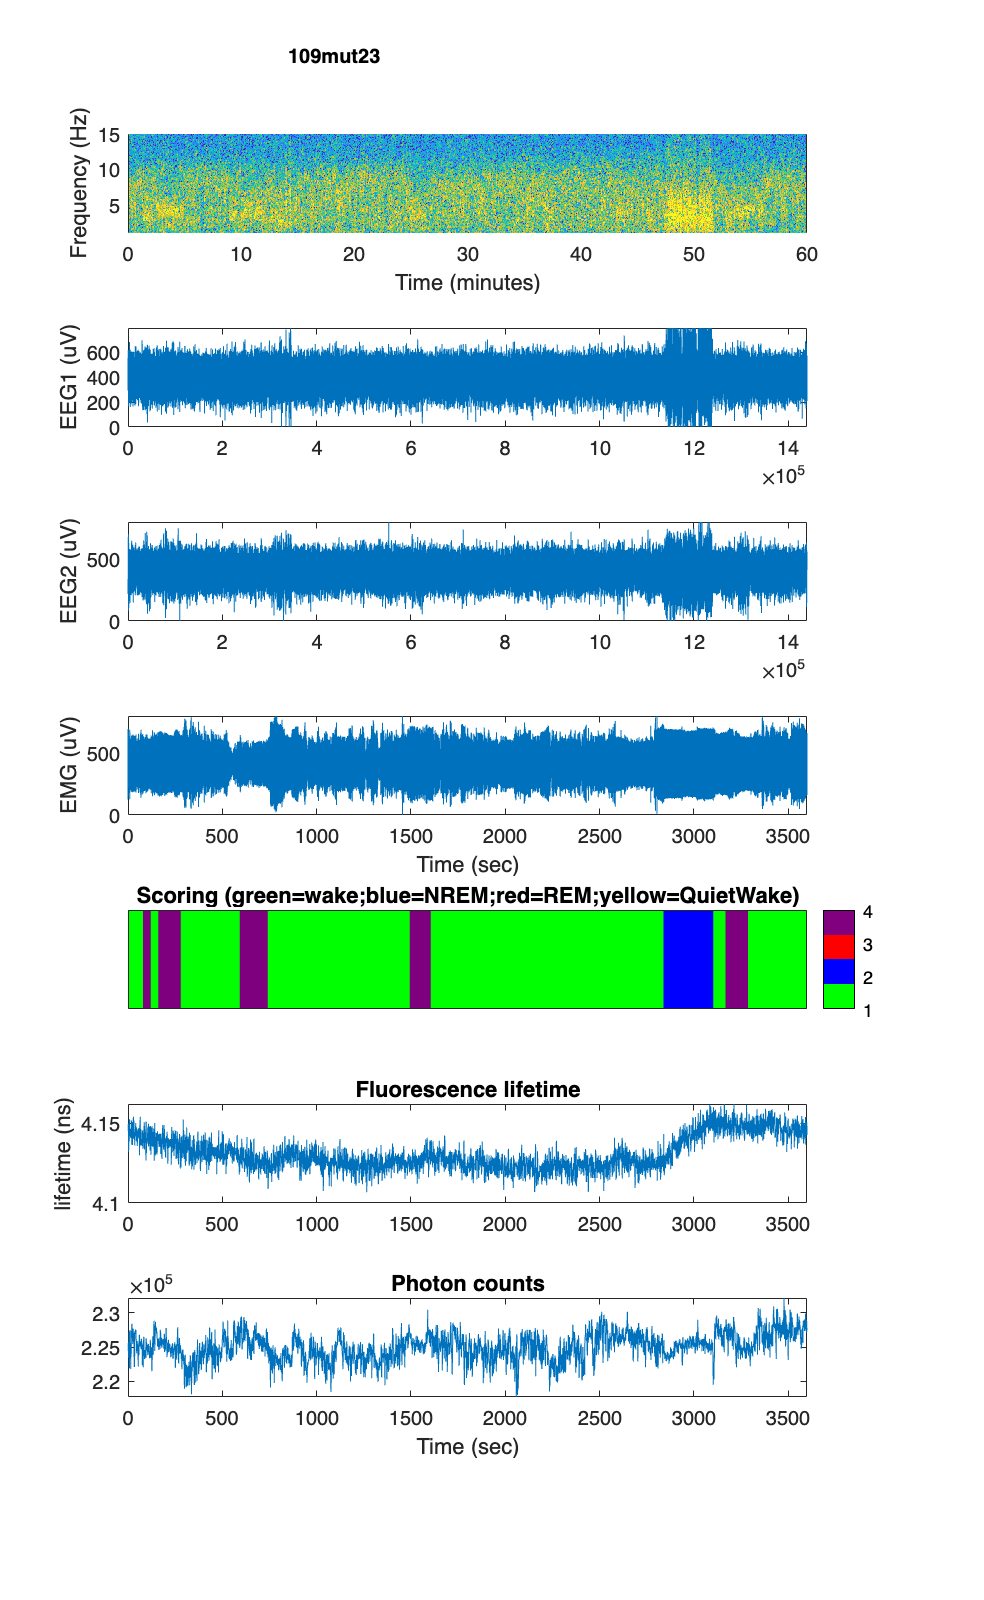


for acqn=Dark_hours(1):Dark_hours(end)
    PlotEEGEMGFLiP(rawdat_dir, mouse, fileprefix, filepostfix, acqn, frequency, constant, FigureVisible);
end


load('FLP_analysis.mat')

Loading wave object  ...
Loading wave object  ...
Loading wave object  ...


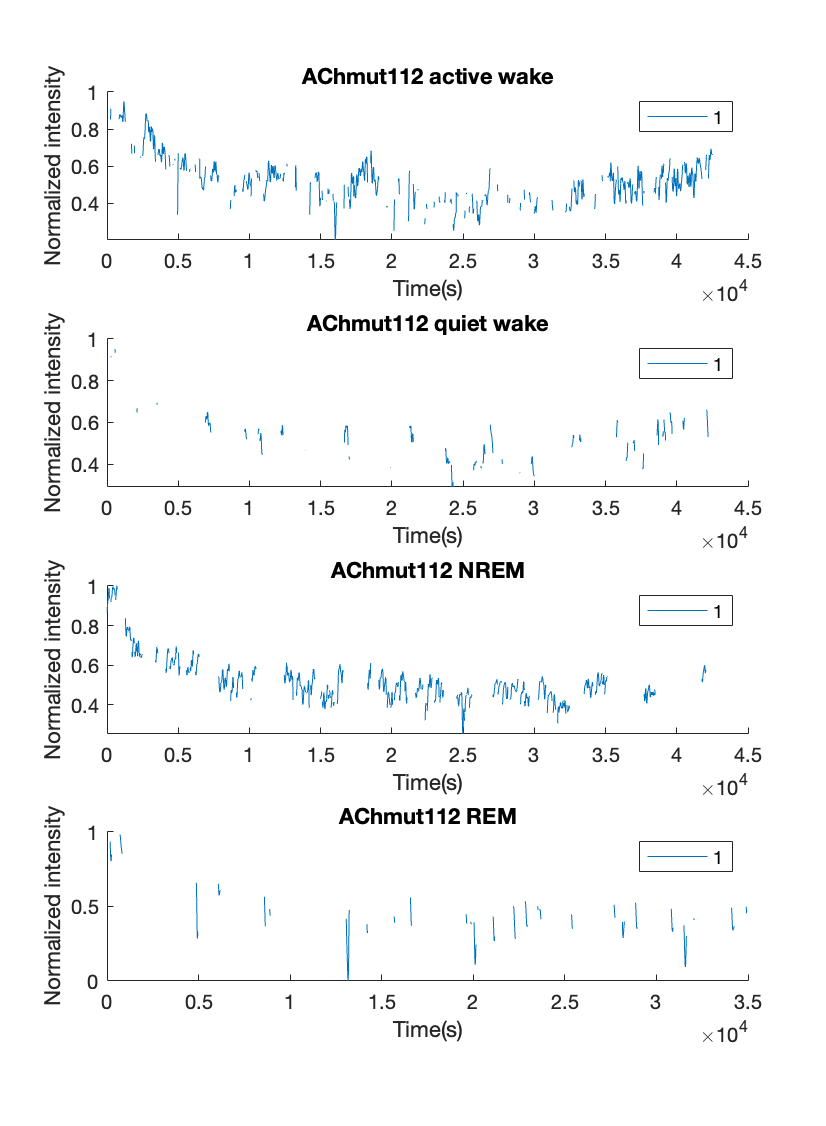

% intensity_all_darkonly(find(intensity_all_darkonly<290000))=NaN;
t1=time_z_all_darkonly;
intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

AW_states=find(states_for_time_all_dark==1);
QW_states=find(states_for_time_all_dark==4);
NREM_states=find(states_for_time_all_dark==2);
REM_states=find(states_for_time_all_dark==3);
                                
AW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
QW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
NREM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
REM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);

AW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
QW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
NREM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
REM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);


for i=1:size(AW_states,1)
    AW_tau1(AW_states(i))=tau_empTrunc_all_darkonly(AW_states(i));
    AW_intensity1(AW_states(i))=intensity_all_darkonly(AW_states(i));
end

for i=1:size(QW_states,1)
    QW_tau1(QW_states(i))=tau_empTrunc_all_darkonly(QW_states(i));
    QW_intensity1(QW_states(i))=intensity_all_darkonly(QW_states(i));
end

for i=1:size(NREM_states,1)
    NREM_tau1(NREM_states(i))=tau_empTrunc_all_darkonly(NREM_states(i));
    NREM_intensity1(NREM_states(i))=intensity_all_darkonly(NREM_states(i));
end

for i=1:size(REM_states,1)
    REM_tau1(REM_states(i))=tau_empTrunc_all_darkonly(REM_states(i));
    REM_intensity1(REM_states(i))=intensity_all_darkonly(REM_states(i));
end

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1, AW_intensity1)
legend('1')
title(['AChmut112 active wake'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')

CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1, QW_intensity1)
legend('1')
title(['AChmut112 quiet wake'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1, NREM_intensity1)
legend('1')
title(['AChmut112 NREM'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')

CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1, REM_intensity1)
legend('1')
title(['AChmut112 REM'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1, ['/Volumes/PcSSDA/AChmut112_1_intensity_CR.png'])

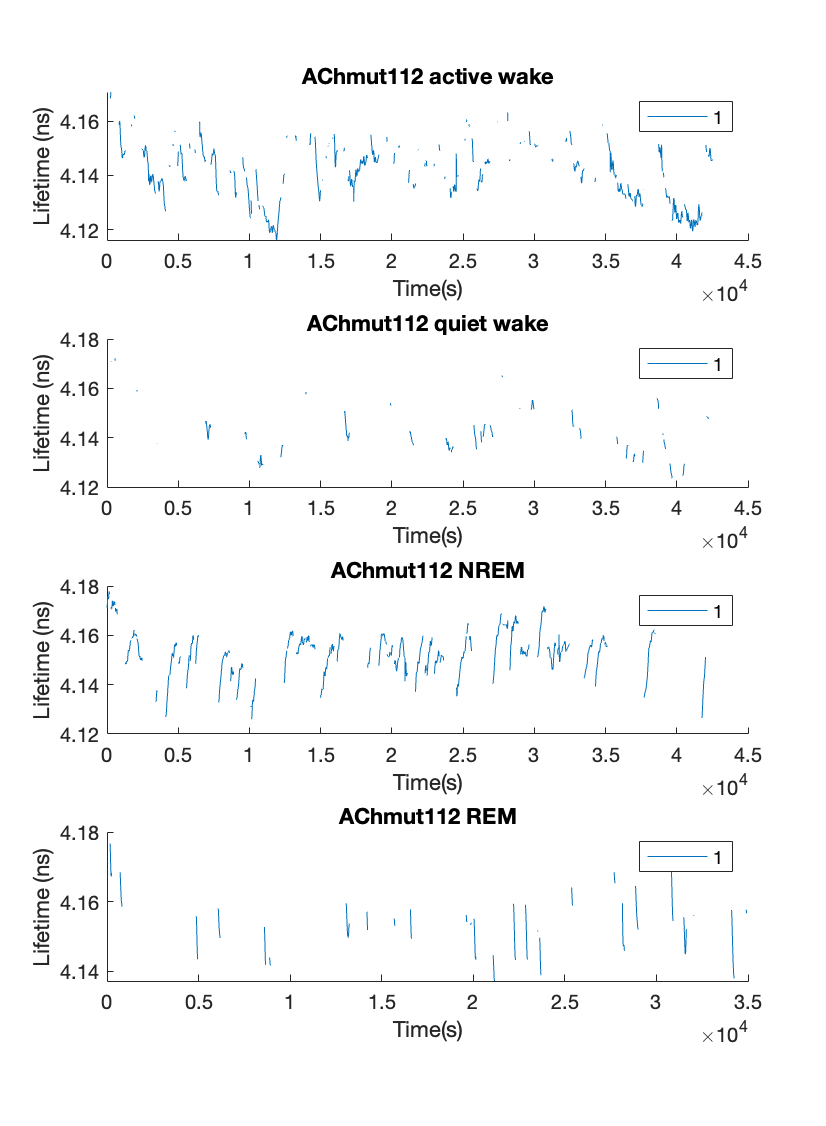


figure2=figure;
figure2.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure2);
hold(CR_plot1,'on')
plot(t1, AW_tau1)
legend('1')
title(['AChmut112 active wake'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot1,'off')

CR_plot2=subplot(4,1,2,'Parent',figure2);
hold(CR_plot2,'on')
plot(t1, QW_tau1)
legend('1')
title(['AChmut112 quiet wake'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure2);
hold(CR_plot3,'on')
plot(t1, NREM_tau1)
legend('1')
title(['AChmut112 NREM'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot3,'off')

CR_plot4=subplot(4,1,4,'Parent',figure2);
hold(CR_plot4,'on')
plot(t1, REM_tau1)
legend('1')
title(['AChmut112 REM'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure2, ['/Volumes/PcSSDA/AChmut112_1_lft_CR.png'])

outlier1=[];
outlier2=[];
outlier3=[];
outlier4=[];

t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_time_1out=[];
median_1out=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];

    if isempty(find(outlier1==i))==0
        median_time_1out=[median_time_1out this_median];
        median_1out=[median_1out median(this_epoch)];
    end
end

median_time_2=[];
median_2=[];
median_time_2out=[];
median_2out=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
    if isempty(find(outlier2==i))==0
        median_time_2out=[median_time_2out this_median];
        median_2out=[median_2out median(this_epoch)];
    end
end

median_time_3=[];
median_3=[];
median_time_3out=[];
median_3out=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
    if isempty(find(outlier3==i))==0
        median_time_3out=[median_time_3out this_median];
        median_3out=[median_3out median(this_epoch)];
    end
end

median_time_4=[];
median_4=[];
median_time_4out=[];
median_4out=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
    if isempty(find(outlier4==i))==0
        median_time_4out=[median_time_4out this_median];
        median_4out=[median_4out median(this_epoch)];
    end
end


t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=intensity_all_darkonly;
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;

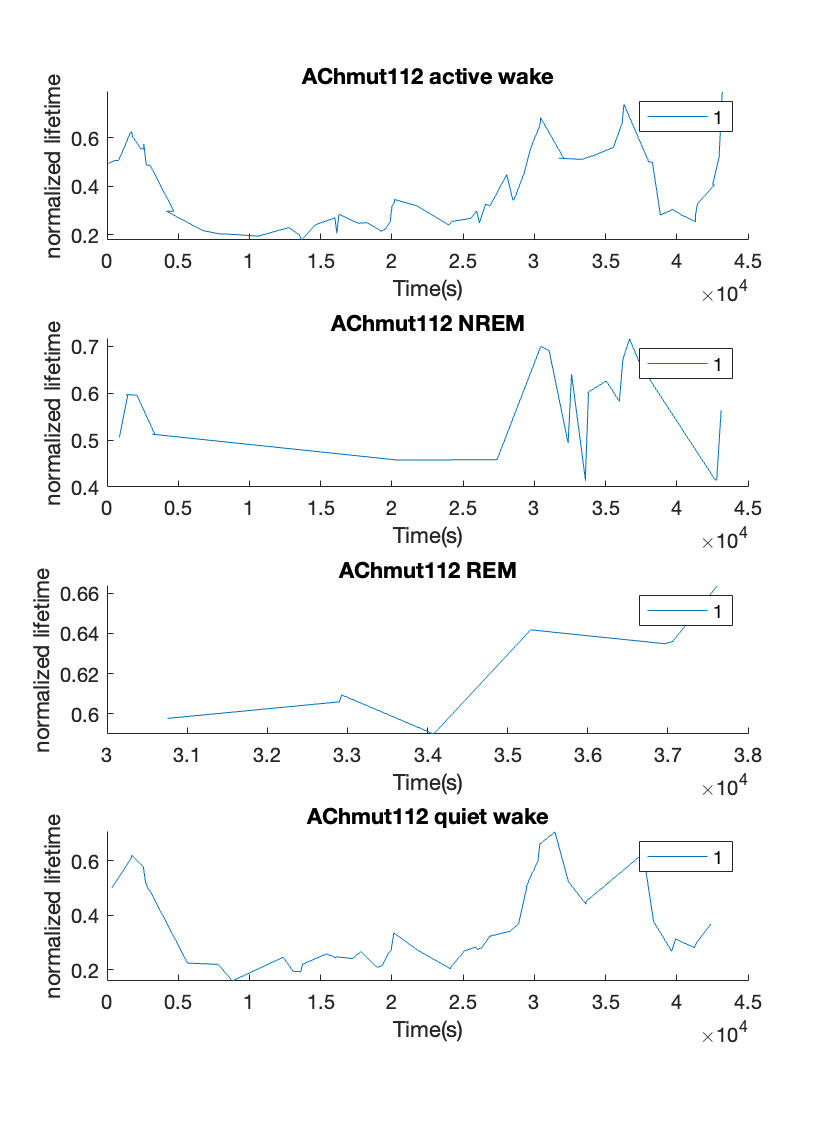

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
legend('1')
title('AChmut112 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
legend('1')
title('AChmut112 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
legend('1')
title('AChmut112 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
legend('1')
title('AChmut112 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/AChmut112_CR_lft_median.png')

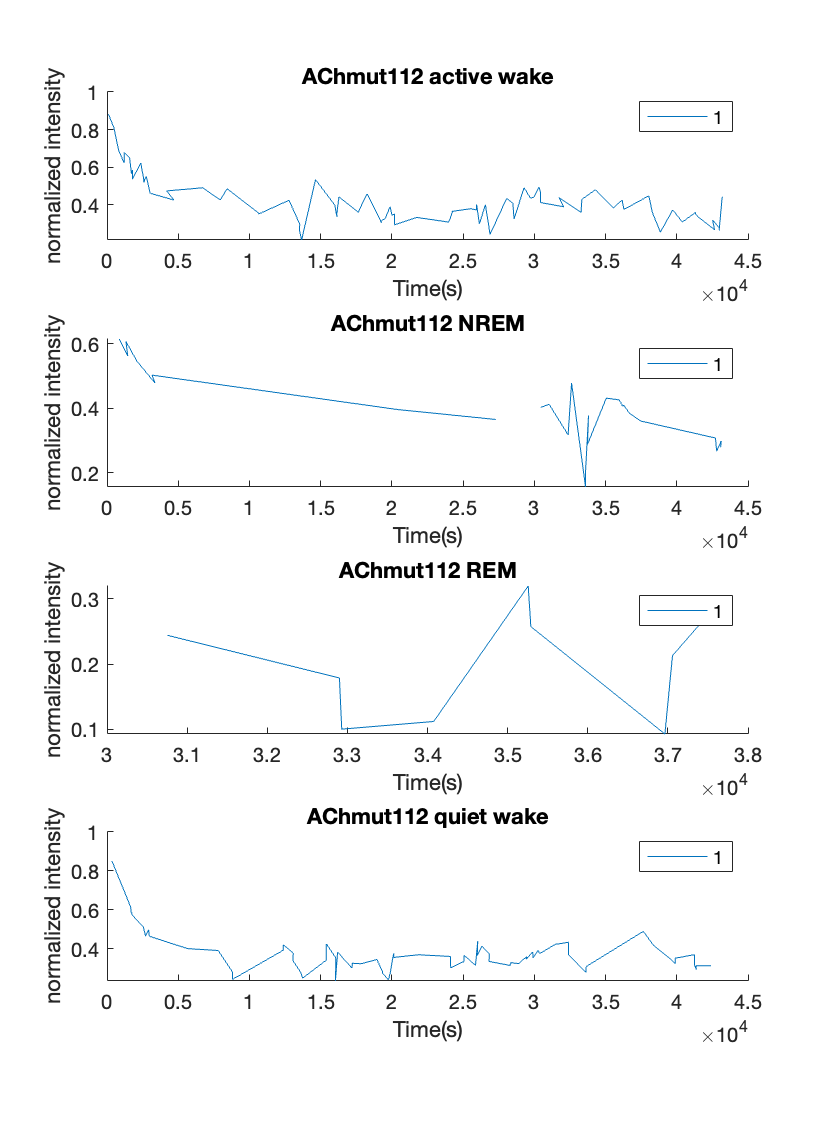

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
legend('1')
title('AChmut112 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
legend('1')
title('AChmut112 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
legend('1')
title('AChmut112 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
legend('1')
title('AChmut112 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/AChmut112_CR_intensity_median.png')

cd('/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001')
ExperimentName='20220207_109_AChMut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 13; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20230106.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

Dot indexing is not supported for variables of this type.

Error in FLiPAnalysis_Tau_p1_Photon (line 39)
Initial(1)=spc.fits{ch}.beta1;

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220207_109_AChMut_SW_001FLIM001.mat'
     folder: '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001'
       date: '07-Feb-2022 17:46:30'
      bytes: 3035
      isdir: 0
    datenum: 7.3856e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20230106.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

Unrecognized function or variable 'FindPeakChannels'.


for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end



if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)



% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['extracted_data/StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

Error using readNPYheader
File not found: extracted_data/StatesAcq20_hr0.npy

Error in readNPY (line 10)
[shape, dataType, fortranOrder, littleEndian, totalHeaderLength, ~] = readNPYheader(filename);


% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end


states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename_plus=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220510.mat'];
    load(filename_plus);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);



mkdir([analysis_name,'csv_20220510'])

csv_name=[analysis_name,'csv_20220510/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)


save('FLP_analysis')

Saving wave object  ...
Saving wave object  ...
Saving wave object  ...


rawdat_dir=pwd;
fileprefix=ExperimentName;% '20220323_1629_SW_003';
filepostfix='20220510';
frequency=1;
constant=FirstAcq-1;
FigureVisible = 'off';
mouse='109mut';


for acqn=Dark_hours(1):Dark_hours(end)
    PlotEEGEMGFLiP(rawdat_dir, mouse, fileprefix, filepostfix, acqn, frequency, constant, FigureVisible);
end

EEGfile = 'extracted_data/downsampEEG_Acq10.npy'

scoring_python = 'extracted_data/StatesAcq10_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_10.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_10.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_10.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_1h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq11.npy'

scoring_python = 'extracted_data/StatesAcq11_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_11.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_11.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_11.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_2h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq12.npy'

scoring_python = 'extracted_data/StatesAcq12_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_12.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_12.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_12.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_3h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq13.npy'

scoring_python = 'extracted_data/StatesAcq13_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_13.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_13.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_13.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_4h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq14.npy'

scoring_python = 'extracted_data/StatesAcq14_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_14.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_14.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_14.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_5h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq15.npy'

scoring_python = 'extracted_data/StatesAcq15_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_15.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_15.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_15.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_6h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq16.npy'

scoring_python = 'extracted_data/StatesAcq16_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_16.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_16.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_16.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_7h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq17.npy'

scoring_python = 'extracted_data/StatesAcq17_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_17.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_17.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_17.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_8h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq18.npy'

scoring_python = 'extracted_data/StatesAcq18_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_18.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_18.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_18.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_9h_20220510.mat'

EEGfile = 'extracted_data/downsampEEG_Acq19.npy'

scoring_python = 'extracted_data/StatesAcq19_hr0.npy'

file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD0_19.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD2_19.mat'

Loading wave object file ...


file = '/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001/AD3_19.mat'

Loading wave object file ...


FLiPfile = '20220207_109_AChMut_SW_001_analysis_10h_20220510.mat'

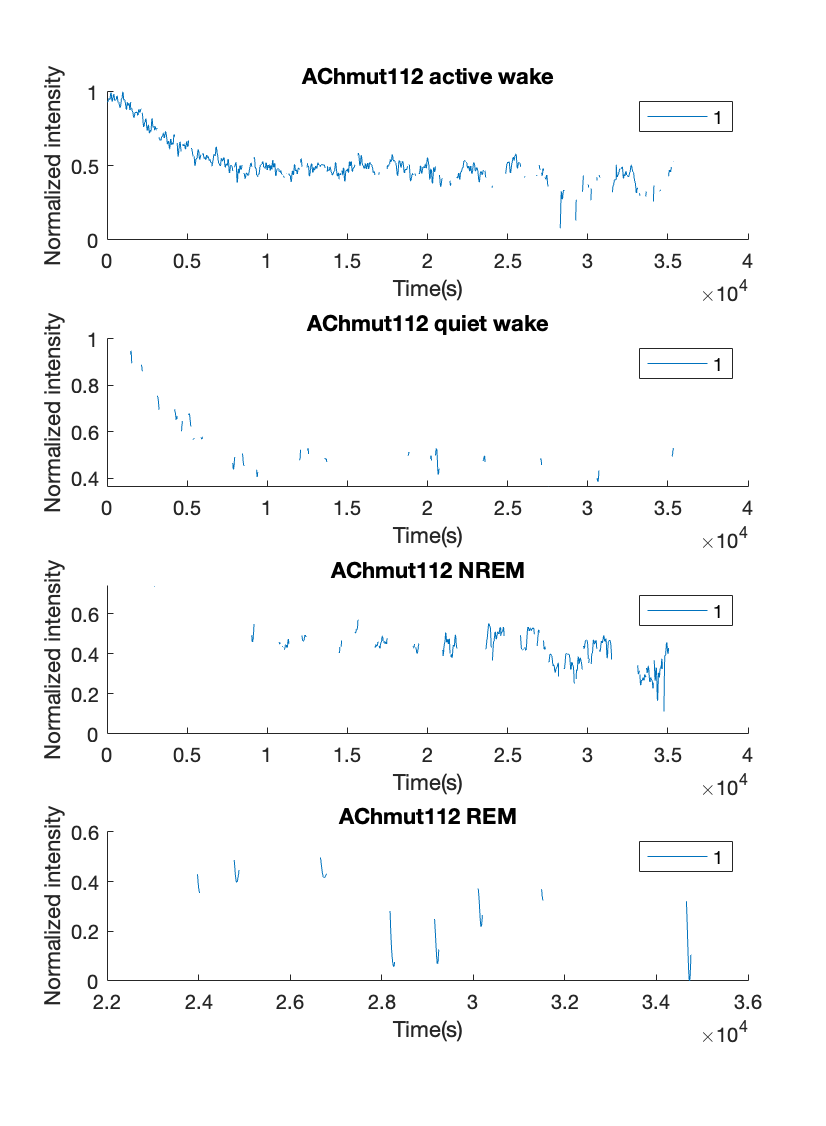


% load('FLP_analysis.mat')
% intensity_all_darkonly(find(intensity_all_darkonly<290000))=NaN;
t1=time_z_all_darkonly;
intensity_all_darkonly=(intensity_all_darkonly-min(intensity_all_darkonly))/range(intensity_all_darkonly);

AW_states=find(states_for_time_all_dark==1);
QW_states=find(states_for_time_all_dark==4);
NREM_states=find(states_for_time_all_dark==2);
REM_states=find(states_for_time_all_dark==3);
                                
AW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
QW_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
NREM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);
REM_tau1=NaN(size(tau_empTrunc_all_darkonly,1),1);

AW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
QW_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
NREM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);
REM_intensity1=NaN(size(tau_empTrunc_all_darkonly,1),1);


for i=1:size(AW_states,1)
    AW_tau1(AW_states(i))=tau_empTrunc_all_darkonly(AW_states(i));
    AW_intensity1(AW_states(i))=intensity_all_darkonly(AW_states(i));
end

for i=1:size(QW_states,1)
    QW_tau1(QW_states(i))=tau_empTrunc_all_darkonly(QW_states(i));
    QW_intensity1(QW_states(i))=intensity_all_darkonly(QW_states(i));
end

for i=1:size(NREM_states,1)
    NREM_tau1(NREM_states(i))=tau_empTrunc_all_darkonly(NREM_states(i));
    NREM_intensity1(NREM_states(i))=intensity_all_darkonly(NREM_states(i));
end

for i=1:size(REM_states,1)
    REM_tau1(REM_states(i))=tau_empTrunc_all_darkonly(REM_states(i));
    REM_intensity1(REM_states(i))=intensity_all_darkonly(REM_states(i));
end

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1, AW_intensity1)
legend('1')
title(['AChmut112 active wake'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')

CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1, QW_intensity1)
legend('1')
title(['AChmut112 quiet wake'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1, NREM_intensity1)
legend('1')
title(['AChmut112 NREM'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')

CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1, REM_intensity1)
legend('1')
title(['AChmut112 REM'])
ylabel('Normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1, ['/Volumes/PcSSDA/AChmut112_2_intensity_CR.png'])

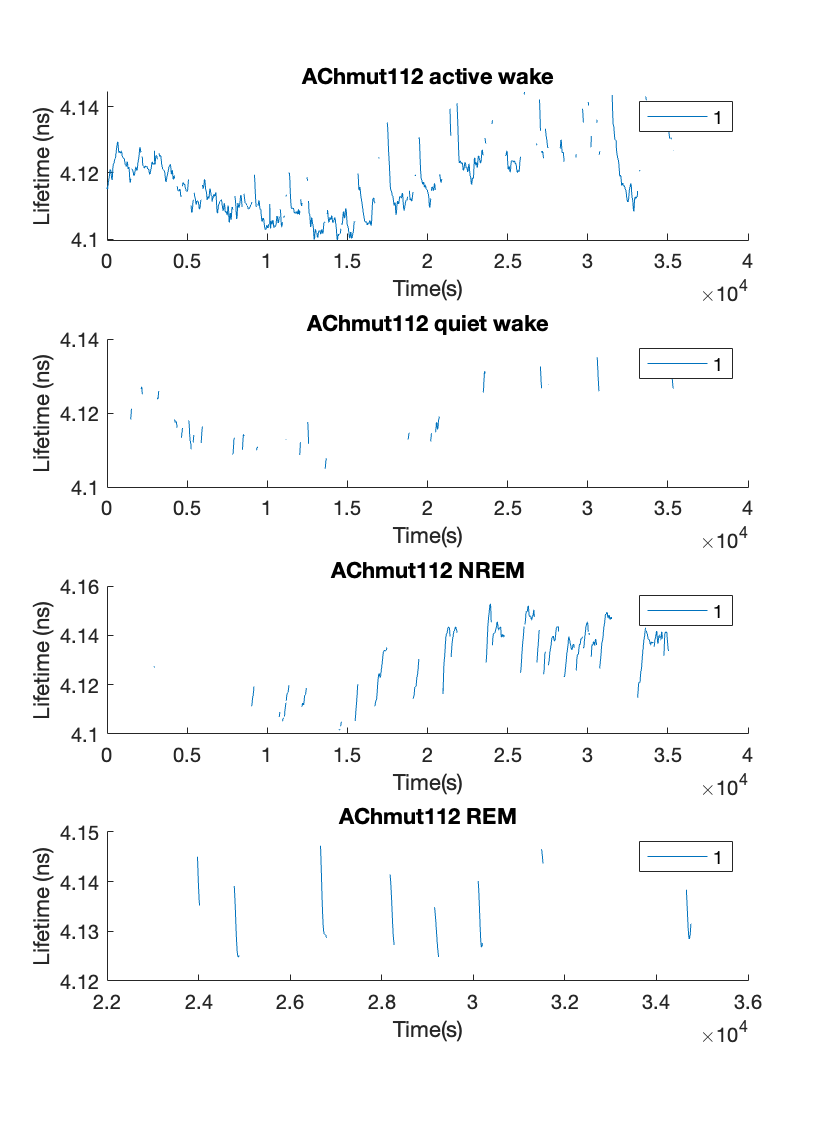


figure2=figure;
figure2.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure2);
hold(CR_plot1,'on')
plot(t1, AW_tau1)
legend('1')
title(['AChmut112 active wake'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot1,'off')

CR_plot2=subplot(4,1,2,'Parent',figure2);
hold(CR_plot2,'on')
plot(t1, QW_tau1)
legend('1')
title(['AChmut112 quiet wake'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure2);
hold(CR_plot3,'on')
plot(t1, NREM_tau1)
legend('1')
title(['AChmut112 NREM'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot3,'off')

CR_plot4=subplot(4,1,4,'Parent',figure2);
hold(CR_plot4,'on')
plot(t1, REM_tau1)
legend('1')
title(['AChmut112 REM'])
ylabel('Lifetime (ns)')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure2, ['/Volumes/PcSSDA/AChmut112_2_lft_CR.png'])

outlier1=[];
outlier2=[];
outlier3=[];
outlier4=[];

t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_time_1out=[];
median_1out=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];

    if isempty(find(outlier1==i))==0
        median_time_1out=[median_time_1out this_median];
        median_1out=[median_1out median(this_epoch)];
    end
end

median_time_2=[];
median_2=[];
median_time_2out=[];
median_2out=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
    if isempty(find(outlier2==i))==0
        median_time_2out=[median_time_2out this_median];
        median_2out=[median_2out median(this_epoch)];
    end
end

median_time_3=[];
median_3=[];
median_time_3out=[];
median_3out=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
    if isempty(find(outlier3==i))==0
        median_time_3out=[median_time_3out this_median];
        median_3out=[median_3out median(this_epoch)];
    end
end

median_time_4=[];
median_4=[];
median_time_4out=[];
median_4out=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
    if isempty(find(outlier4==i))==0
        median_time_4out=[median_time_4out this_median];
        median_4out=[median_4out median(this_epoch)];
    end
end


t1=time_z_all_darkonly;
lft1=(tau_empTrunc_all_darkonly-min(tau_empTrunc_all_darkonly))/range(tau_empTrunc_all_darkonly);
intensity1=intensity_all_darkonly;
median_time_1a=median_time_1;
median_time_2a=median_time_2;
median_time_3a=median_time_3;
median_time_4a=median_time_4;

figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),lft1(median_time_1a))
legend('1')
title('AChmut112 active wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),lft1(median_time_2a))
legend('1')
title('AChmut112 NREM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),lft1(median_time_3a))
legend('1')
title('AChmut112 REM')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),lft1(median_time_4a))
legend('1')
title('AChmut112 quiet wake')
ylabel('normalized lifetime')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/AChmut112_CR_lft_median.png')


figure1=figure;
figure1.Position=[10 10 1100 1500];

CR_plot1=subplot(4,1,1,'Parent',figure1);
hold(CR_plot1,'on')
plot(t1(median_time_1a),intensity1(median_time_1a))
legend('1')
title('AChmut112 active wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot1,'off')


CR_plot2=subplot(4,1,2,'Parent',figure1);
hold(CR_plot2,'on')
plot(t1(median_time_2a),intensity1(median_time_2a))
legend('1')
title('AChmut112 NREM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot2,'off')

CR_plot3=subplot(4,1,3,'Parent',figure1);
hold(CR_plot3,'on')
plot(t1(median_time_3a),intensity1(median_time_3a))
legend('1')
title('AChmut112 REM')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot3,'off')


CR_plot4=subplot(4,1,4,'Parent',figure1);
hold(CR_plot4,'on')
plot(t1(median_time_4a),intensity1(median_time_4a))
legend('1')
title('AChmut112 quiet wake')
ylabel('normalized intensity')
xlabel('Time(s)')
hold(CR_plot4,'off')

saveas(figure1,'/Volumes/PcSSDA/AChmut112_CR_intensity_median.png')
